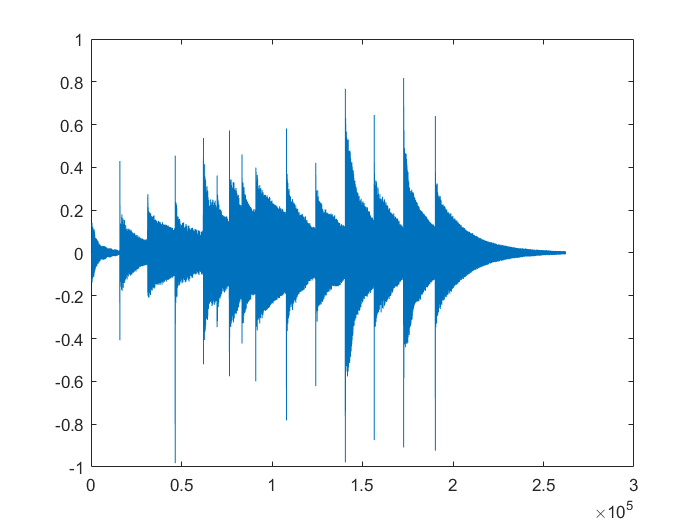

clear variables;
close all;
clc;
[audio,sr] = audioread('glockenspiel.wav');
plot(audio)

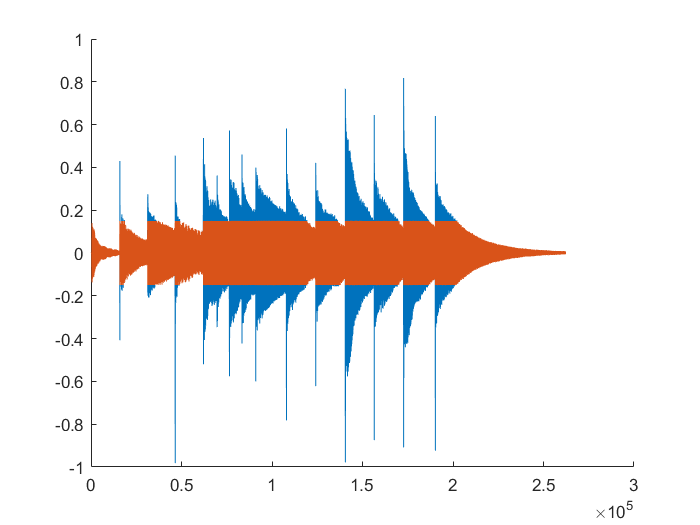

[Clipped_signal,Clipping_Level] = Clipping_signal (audio, 10);
figure;
hold on;
plot(audio)
plot(Clipped_signal)

#### Signal clipping

function SNR = SNR(a, b)    
    SNR = 20*log10(norm(a)/norm(a-b));
end

function  [Clipped_signal,Clipping_Level]= Clipping_signal (signal, SNR_target)
    ClippingLevel1 = 0;
    ClippingLevel2 = max(abs(signal));
    it = 0;
    SNRtmp=Inf;
    while abs(SNRtmp-SNR_target) > 0.001 && it < 20
        it = it + 1;
        Clipping_Level = (ClippingLevel1+ClippingLevel2)/2;

        Clipped_signal = max(min(signal,Clipping_Level),-Clipping_Level);
        SNRtmp = SNR(signal,Clipped_signal);
        if SNRtmp < SNR_target
            ClippingLevel1 = Clipping_Level;
        else
            ClippingLevel2 = Clipping_Level;
        end
    end
end